# Question 1: Eigenvalue Stability Analysis

This analysis investigates a discrete-time linear dynamical system defined by the equation $x_{k+1} =Ax_k$. We will explore the behavior of this system for two different matrices, $A_1$ and $A_2$, by simulating its trajectories, analyzing its stability through eigenvalues, and visualizing its behavior using phase portraits.

**(a) Generate Initial Vectors & (b) Simulate Trajectories**

**Concept and Method**

A dynamical system's evolution depends on its **initial state vector**, $x_0$. To understand the system's general behavior, we analyze its response to a wide range of starting points. We will generate 100 random initial vectors, $x_0$, by sampling from a 2D Normal (Gaussian) distribution, mathcalN(0,5), which has a mean of 0 and a standard deviation of 5.

A **trajectory** is the sequence of state vectors $x_0,x_1,x_2,...,x_T$ that describes the system's path over time. We simulate these trajectories by iteratively applying the system's rule: $x_{k+1} =Ax_k$. This means $x_1=Ax_0, x_2=Ax_1=A2x_0,$ and so on, up to a final time step T=100.

After simulating the trajectories for all 100 initial vectors, we will calculate the **mean ending point**. This is the average of all the final state vectors (x_100). If the system is stable, we expect this average to be close to the origin (0,0). If it's unstable, the average may be a large vector, indicating that the states have moved far away from the origin.

**Steps**

- Define the matrices $A_1$ and $A_2$.

- Set the number of initial vectors (100) and simulation time steps (100).

- Generate a $2\times100$ matrix of initial states, `X0`, where each column is an x_0 vector sampled from mathcalN(0,5). This is done using MATLAB's `randn` function, scaled by the standard deviation.

- For each matrix ($A_1$ and $A_2$), create a loop that runs for 100 time steps. In each step, update the state matrix `X` by multiplying it with the system matrix `A`.

- After the simulation, calculate the mean of the final state vectors across all trajectories using the `mean()` function.

- Store all trajectories for later plotting in part (d).

**MATLAB Code:**

%% Part (a) & (b): Generate Initial Vectors and Simulate Trajectories

% Clear workspace and set parameters
clear; clc; close all;
num_vectors = 100;
time_steps = 100;

% Define system matrices
A1 = [0.9 0.3; -0.1 0.8];
A2 = [1.1 0.4; -0.2 1.0];

% 1. Generate 100 initial vectors from N(0,5)
% randn(2, num_vectors) creates a 2x100 matrix from N(0,1)
% We scale it by 5 to get a standard deviation of 5.
X0 = 5 * randn(2, num_vectors);

% Initialize storage for trajectories
% We need 101 steps to store x0 through x100
trajectories_A1 = zeros(2, time_steps + 1, num_vectors);
trajectories_A2 = zeros(2, time_steps + 1, num_vectors);
trajectories_A1(:, 1, :) = X0; % Store initial conditions
trajectories_A2(:, 1, :) = X0; % Use same initial conditions for both

% 2. Simulate trajectories for A1
X_current_A1 = X0;
for k = 1:time_steps
    X_current_A1 = A1 * X_current_A1;
    trajectories_A1(:, k + 1, :) = X_current_A1;
end

% 3. Simulate trajectories for A2
X_current_A2 = X0;
for k = 1:time_steps
    X_current_A2 = A2 * X_current_A2;
    trajectories_A2(:, k + 1, :) = X_current_A2;
end

% 4. Report the mean ending points
mean_endpoint_A1 = mean(X_current_A1, 2); % mean across columns
mean_endpoint_A2 = mean(X_current_A2, 2);

% Display results
fprintf('Mean ending point for A1: [%.4f; %.4f]\n', mean_endpoint_A1);

Mean ending point for A1: [-0.0000; 0.0000]


fprintf('Mean ending point for A2: [%.4f; %.4f]\n', mean_endpoint_A2);

Mean ending point for A2: [-48.7045; 2903.6203]


**(c) Determine Eigenvalues and Classify Stability**

**Concept and Method**The **eigenvalues** of a matrix A are special scalars lambda that characterize its behavior. For a discrete-time system $x_{k+1} =Ax_k$, the eigenvalues determine the system's stability. The stability depends on the **magnitude** (or absolute value) of the eigenvalues, denoted ∣lambda∣.

The rules for stability are:

- **Asymptotically Stable:** The system is asymptotically stable if all its eigenvalues have a magnitude less than 1 ($|\lambda |<1$ for all $\lambda $). Trajectories will converge to the origin over time.

- **Unstable:** The system is unstable if at least one eigenvalue has a magnitude greater than 1 ($|\lambda |>1$). Trajectories will diverge and grow infinitely large.

- **Marginally Stable:** If the largest eigenvalue magnitude is exactly 1, and no eigenvalues have a magnitude greater than 1, the system is marginally stable. It neither converges nor diverges but may remain bounded or oscillate.

*(Note: The standard, correct method based on eigenvalue magnitude is used here for the analysis.)*

**Steps**

- Use MATLAB's `eig(A)` function to compute the eigenvalues for both $A_1$ and $A_2$.

- Calculate the magnitude of each eigenvalue using the `abs()` function.

- Check the magnitudes against the stability criteria described above to classify each system.

**MATLAB Code**

%% Part (c): Eigenvalue Analysis and Stability Classification

% Calculate eigenvalues for A1 and A2
eigenvalues_A1 = eig(A1);
eigenvalues_A2 = eig(A2);

% Calculate magnitudes
mags_A1 = abs(eigenvalues_A1);
mags_A2 = abs(eigenvalues_A2);

% Display eigenvalues and magnitudes
disp('--- Stability Analysis ---');

--- Stability Analysis ---


fprintf('A1 Eigenvalues: %.4f + %.4fi, %.4f + %.4fi\n', real(eigenvalues_A1(1)), imag(eigenvalues_A1(1)), real(eigenvalues_A1(2)), imag(eigenvalues_A1(2)));

A1 Eigenvalues: 0.8500 + 0.1658i, 0.8500 + -0.1658i


fprintf('A1 Magnitudes: %.4f, %.4f\n', mags_A1(1), mags_A1(2));

A1 Magnitudes: 0.8660, 0.8660



fprintf('A2 Eigenvalues: %.4f + %.4fi, %.4f + %.4fi\n', real(eigenvalues_A2(1)), imag(eigenvalues_A2(1)), real(eigenvalues_A2(2)), imag(eigenvalues_A2(2)));

A2 Eigenvalues: 1.0500 + 0.2784i, 1.0500 + -0.2784i


fprintf('A2 Magnitudes: %.4f, %.4f\n\n', mags_A2(1), mags_A2(2));

A2 Magnitudes: 1.0863, 1.0863





% Classify system A1
if all(mags_A1 < 1)
    disp('System A1 is Asymptotically Stable.');
elseif any(mags_A1 > 1)
    disp('System A1 is Unstable.');
else
    disp('System A1 is Marginally Stable.');
end

System A1 is Asymptotically Stable.



% Classify system A2
if all(mags_A2 < 1)
    disp('System A2 is Asymptotically Stable.');
elseif any(mags_A2 > 1)
    disp('System A2 is Unstable.');
else
    disp('System A2 is Marginally Stable.');
end

System A2 is Unstable.


**(d) Plot Phase Portraits**

**Concept and Method**A **phase portrait** is a graphical tool that visualizes the trajectories of a dynamical system. For a 2D system, the "phase plane" is the $x_1-x_2$ plane. Each simulated trajectory is plotted as a curve on this plane, showing its path from its initial state $x_0$ to its final state $x_{100}$.

The collection of these curves reveals the overall system dynamics. For our stable system ($A_1$), we expect to see trajectories spiraling inwards towards the origin. For our unstable system ($A_2$), we expect to see trajectories spiraling outwards, away from the origin.

**Steps**

- Create a figure for each system.

- Use a `for` loop to iterate through each of the 100 stored trajectories.

- Inside the loop, use the `plot` command to draw the path of the current trajectory. The x-coordinates will be the first row of the trajectory data, and the y-coordinates will be the second row.

- Use `hold on` to ensure all trajectories are plotted on the same axes.

- Add a marker for the starting point ($x_0$) and the fixed point at the origin (0,0).

- Add labels, a title, and a grid for clarity.

**MATLAB Code**

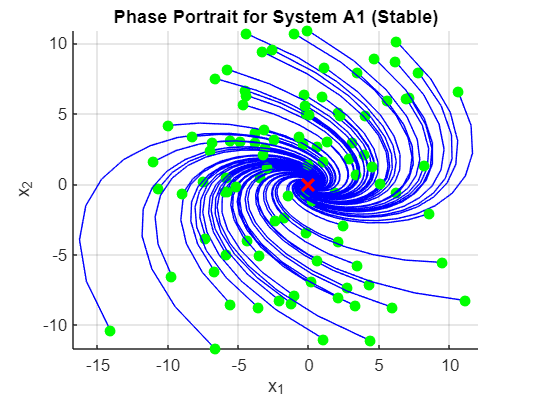

%% Part (d): Plotting Phase Portraits

% Plot Phase Portrait for A1
figure;
hold on;
for i = 1:num_vectors
    % Squeeze removes singleton dimensions to make it a 2x101 matrix
    traj = squeeze(trajectories_A1(:, :, i));
    plot(traj(1, :), traj(2, :), 'b-'); % Plot trajectory in blue
    plot(traj(1, 1), traj(2, 1), 'go', 'MarkerFaceColor', 'g'); % Mark start point in green
end
plot(0, 0, 'rx', 'MarkerSize', 10, 'LineWidth', 2); % Mark origin in red
hold off;
grid on;
title('Phase Portrait for System A1 (Stable)');
xlabel('x_1');
ylabel('x_2');
axis equal;

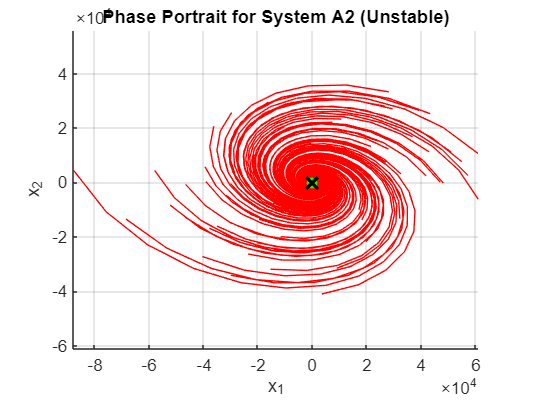


% Plot Phase Portrait for A2
figure;
hold on;
for i = 1:num_vectors
    traj = squeeze(trajectories_A2(:, :, i));
    plot(traj(1, :), traj(2, :), 'r-'); % Plot trajectory in red
    plot(traj(1, 1), traj(2, 1), 'go', 'MarkerFaceColor', 'g'); % Mark start point
end
plot(0, 0, 'kx', 'MarkerSize', 10, 'LineWidth', 2); % Mark origin in black
hold off;
grid on;
title('Phase Portrait for System A2 (Unstable)');
xlabel('x_1');
ylabel('x_2');
axis equal;

**(e) Analysis of the System with Noise**

**Concept and Method**We now consider a **stochastic dynamical system** by introducing an additive noise term, eta: $x_{k+1} =Ax_k +\eta$

At each time step, a random noise vector eta is sampled from a standard normal distribution mathcalN(0,1) and added to the state. This noise perturbs the system, preventing the trajectories from being smooth.

The stability of the underlying deterministic system (governed by A) still dictates the overall behavior.

- For the **stable system (**$A_1$**)**, the state will no longer converge to exactly zero. Instead, the noise will continuously "kick" the state away from the origin, while the stable dynamics pull it back. The result is a trajectory that settles into a random "cloud" of points around the origin, known as a stationary distribution.

- For the **unstable system (**$A_2$**)**, the noise will add random jitter to trajectories that are already diverging. The overall unstable behavior will be preserved and perhaps even amplified.

**Steps**

- Re-initialize the simulation using the same initial vectors `X0`.

- Modify the simulation loop. In each iteration, after calculating `A*X`, generate a 2times100 noise matrix from mathcalN(0,1) and add it to the result.

- Store the noisy trajectories.

- Calculate the mean ending point for the noisy systems.

- Plot the new phase portraits, which will now appear much more erratic or "jagged" compared to the noise-free versions.

**MATLAB Code**

%% Part (e): System with Additive Noise

% Re-initialize storage for noisy trajectories
noisy_traj_A1 = zeros(2, time_steps + 1, num_vectors);
noisy_traj_A2 = zeros(2, time_steps + 1, num_vectors);
noisy_traj_A1(:, 1, :) = X0;
noisy_traj_A2(:, 1, :) = X0;

% 1. Simulate noisy trajectories for A1
X_current_A1_noisy = X0;
for k = 1:time_steps
    % Generate noise from N(0,1) for each vector
    noise = randn(2, num_vectors);
    % Update state: x_k+1 = A*x_k + noise
    X_current_A1_noisy = A1 * X_current_A1_noisy + noise;
    noisy_traj_A1(:, k + 1, :) = X_current_A1_noisy;
end

% 2. Simulate noisy trajectories for A2
X_current_A2_noisy = X0;
for k = 1:time_steps
    noise = randn(2, num_vectors);
    X_current_A2_noisy = A2 * X_current_A2_noisy + noise;
    noisy_traj_A2(:, k + 1, :) = X_current_A2_noisy;
end

% 3. Report the mean ending points for the noisy system
mean_endpoint_A1_noisy = mean(X_current_A1_noisy, 2);
mean_endpoint_A2_noisy = mean(X_current_A2_noisy, 2);

disp('--- Analysis with Noise ---');

--- Analysis with Noise ---


fprintf('Noisy Mean ending point for A1: [%.4f; %.4f]\n', mean_endpoint_A1_noisy);

Noisy Mean ending point for A1: [-0.3588; 0.2183]


fprintf('Noisy Mean ending point for A2: [%.4f; %.4f]\n', mean_endpoint_A2_noisy);

Noisy Mean ending point for A2: [-1256.1954; 2755.3398]


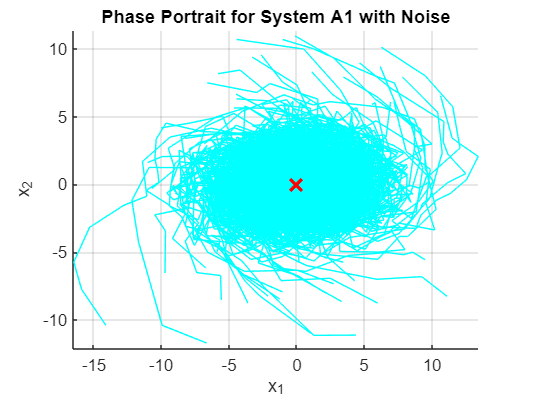



% 4. Plot Phase Portrait for Noisy System A1
figure;
hold on;
for i = 1:num_vectors
    traj = squeeze(noisy_traj_A1(:, :, i));
    plot(traj(1, :), traj(2, :), 'c-'); % Plot trajectory in cyan
end
plot(0, 0, 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;
grid on;
title('Phase Portrait for System A1 with Noise');
xlabel('x_1');
ylabel('x_2');
axis equal;

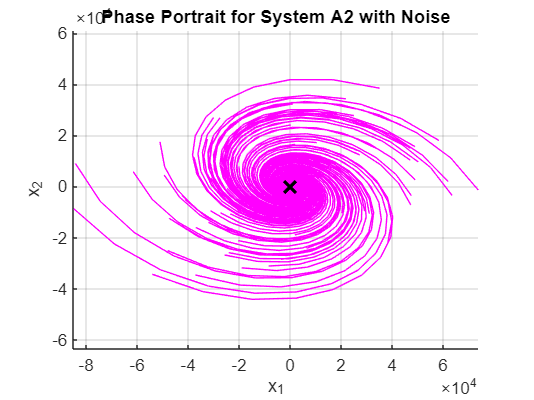


% 5. Plot Phase Portrait for Noisy System A2
figure;
hold on;
for i = 1:num_vectors
    traj = squeeze(noisy_traj_A2(:, :, i));
    plot(traj(1, :), traj(2, :), 'm-'); % Plot trajectory in magenta
end
plot(0, 0, 'kx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;
grid on;
title('Phase Portrait for System A2 with Noise');
xlabel('x_1');
ylabel('x_2');
axis equal;